# Decimation

clc;
close all;

fs = 16

clear all;

Def. reducing a sampling rate of a signal bei a factor of D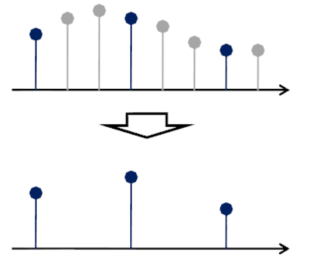

- new sampling frequency still has to fulfill sampling theorem

- to fulfill the sampling frequency it is useful to limit the highest frequency with a TP

- in this case the frequencyresponse has the form

#### Signal definition

len=1;%[s]
fs=16%[Hz]
Ts=1/fs;%time between samples
n=[0:1:len*fs-1];%2 seconds of sampling meaning i have 32 values
n=n/length(n);%normalize
f=1;%signal frequency
w=2*pi*f;%circular frequency

n_D =          0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750


D=2;
n_D=[0:1:len*fs/D-1];
n_D=n_D/length(n_D)

if false
s=exp(i*w*n)+exp(i*2*pi*2*f*n);
s_D=exp(i*w*n_D)+exp(i*2*pi*2*f*n_D)
else
s=exp(i*w*n);   
s_D=exp(i*w*n_D);   
end


#### Signal Representation normal 

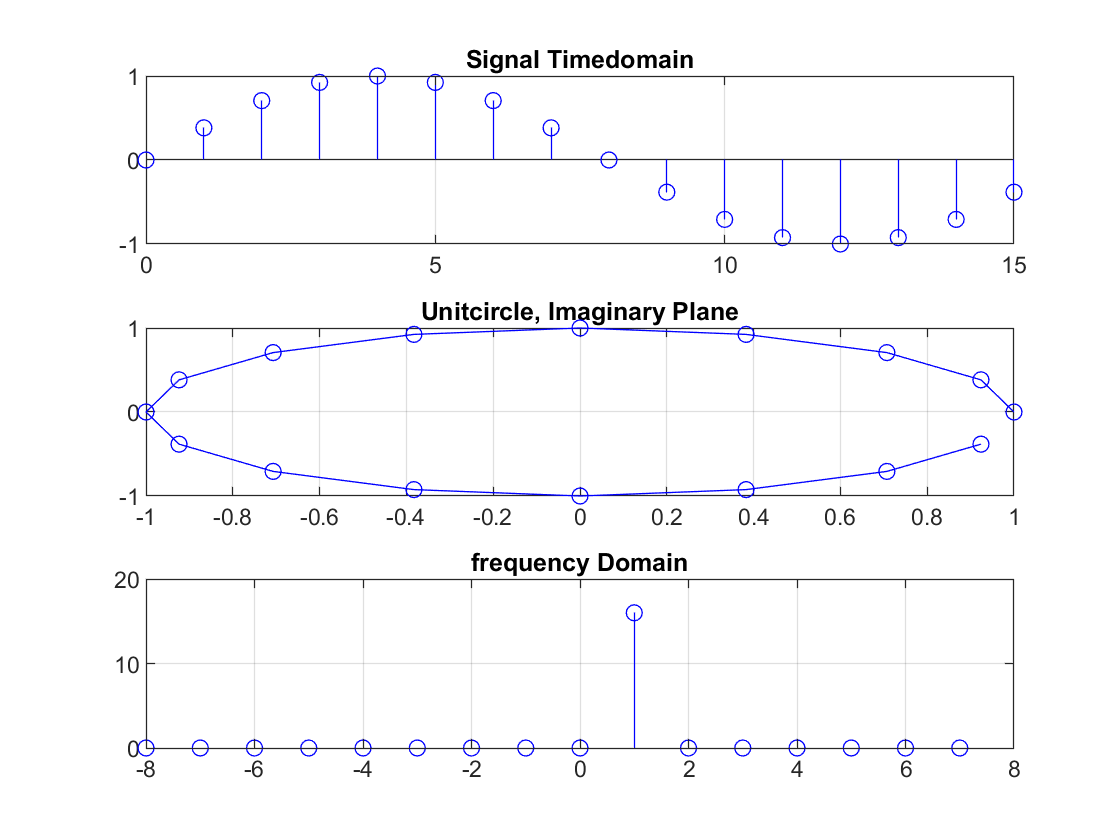

figure(1);
subplot(3,1,1)
stem([0:1:length(n)-1],imag(s),'-bo')
title('Signal Timedomain')
grid on;
subplot(3,1,2)
plot(real(s),imag(s),'-bo')
title('Unitcircle, Imaginary Plane')
grid on;
subplot(3,1,3)
stem([-length(n)/2:1:length(n)/2-1],fftshift(abs((fft(s)))),'-bo')
title('frequency Domain')

grid on;

#### Signal Representation normal vs Downsampled by D

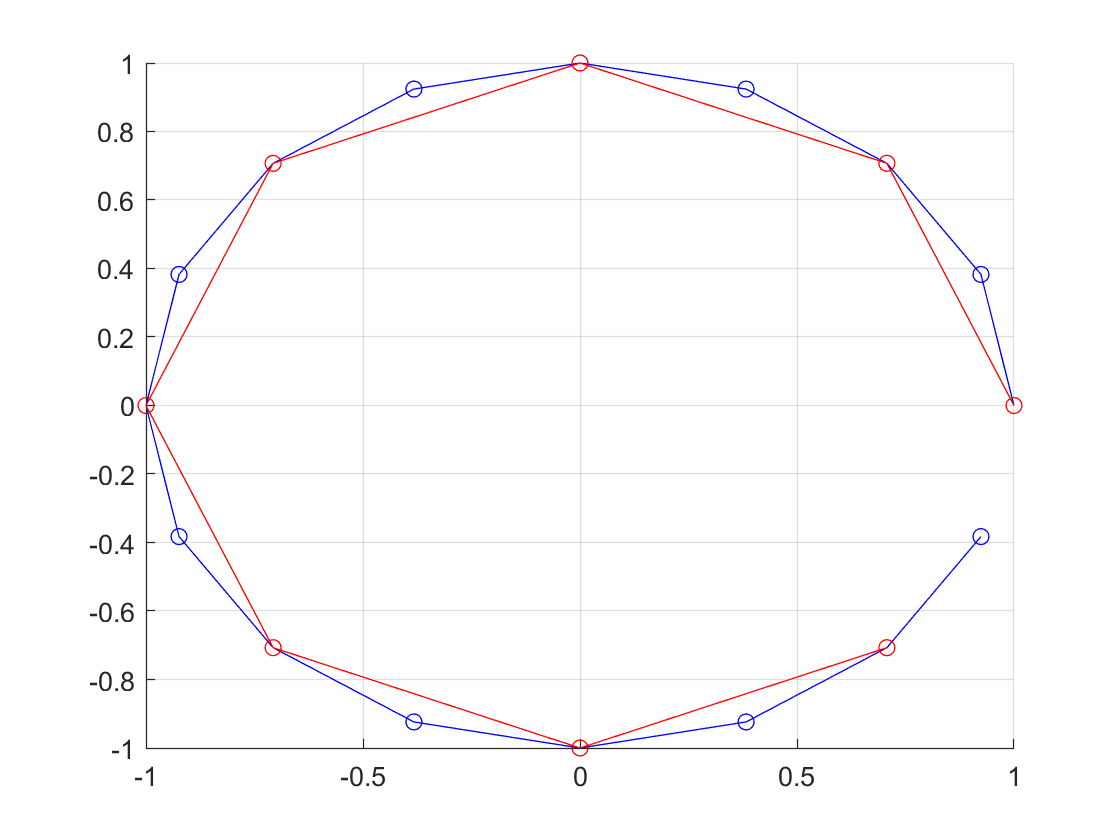


figure;
hold on;
plot(real(s),imag(s),'-bo');
plot(real(s_D),imag(s_D),'-ro');
grid on;
hold off;

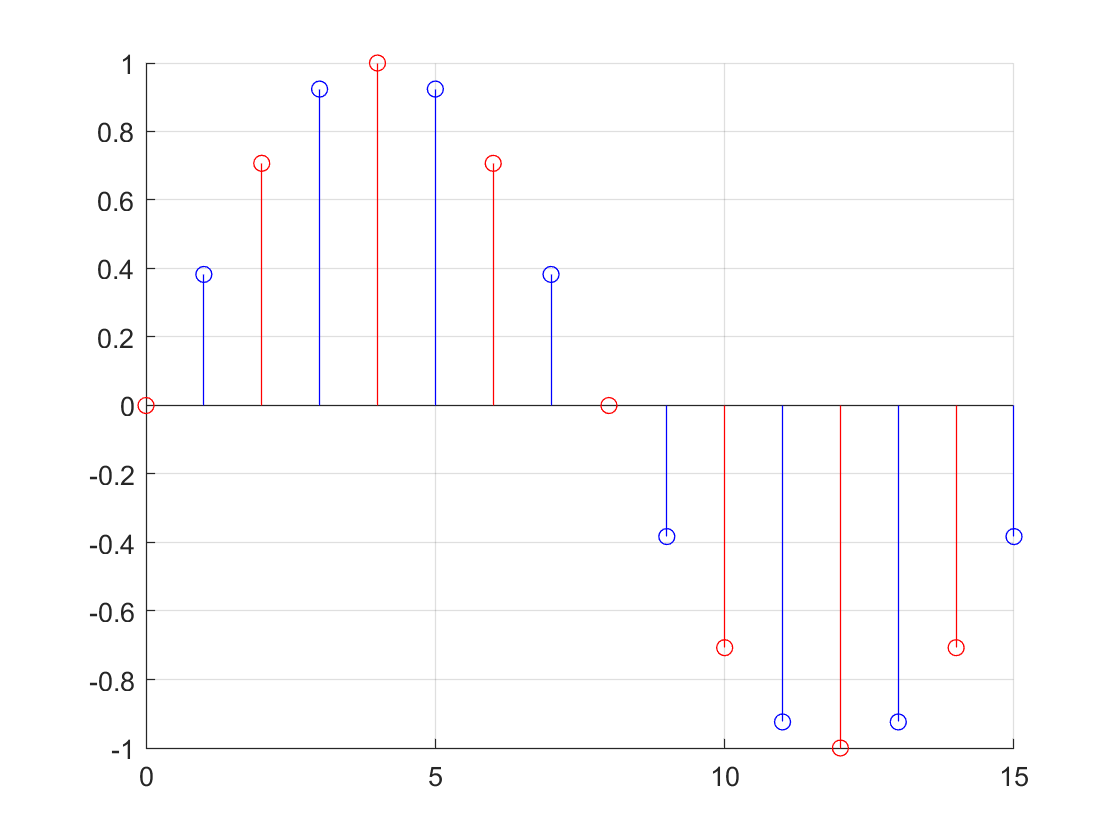

figure;
hold on;
stem([0:1:length(n)-1],imag(s),'-bo')
stem([0:D:length(n)-1],imag(s_D),'-ro')
hold off;
grid on;

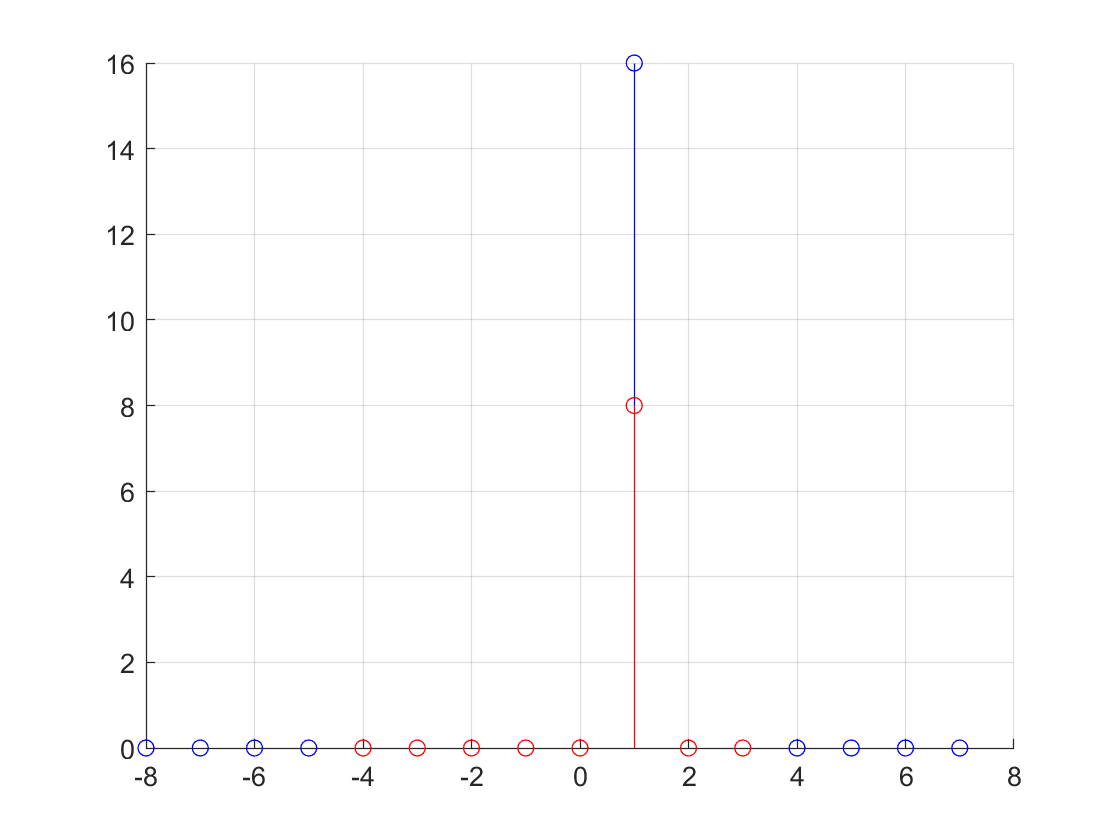

figure;
hold on;
stem([-length(n)/2:1:length(n)/2-1],fftshift(abs((fft(s)))),'-bo')
stem([-length(n_D)/2:1:length(n_D)/2-1],fftshift(abs((fft(s_D)))),'-ro')
hold off;
grid on;

#### Questions

- how can i formulate an impulseresponse that does exactli what a downsampler does ?

- Why isn't the spectrum twosided?

Lowpass Filter 